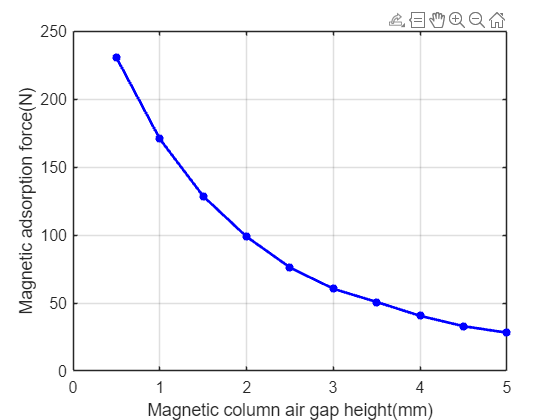

clear
clc
% 导入数据文件
data = load('data4b.csv');
 
% 提取X轴和Y轴上的数值向量
x_values = data(:, 1); % 第一列为X轴数据
y_values =data(:, 2); % 第二列为Y轴数据

% 绘制曲线图
figure; % 创建新的图形窗口
plot(x_values, y_values,'blue-*','MarkerIndices',1:1:length(y_values),'LineWidth',2)
set(gca,'XTick',0:1:5);
set(gca,'XTicklabel',{'0','1','2','3','4','5'})
set(gca,'YTick',0:50:250);
set(gca,'YTicklabel',{'0','50','100','150','200','250'})
axis([0 5 0 250])

xlabel('Magnetic column air gap height(mm)')
ylabel('Magnetic adsorption force(N)')
set(gca,'FontSize',12)

ax.XLabel.FontName = 'Arial';
ax.YLabel.FontName = 'Arial';

grid on; % 打开网格

% 获取当前坐标轴对象
ax = gca;

% 设置网格线的透明度
ax.GridAlpha = 0.15; % 值越小，网格线越浅（越透明）

grid on